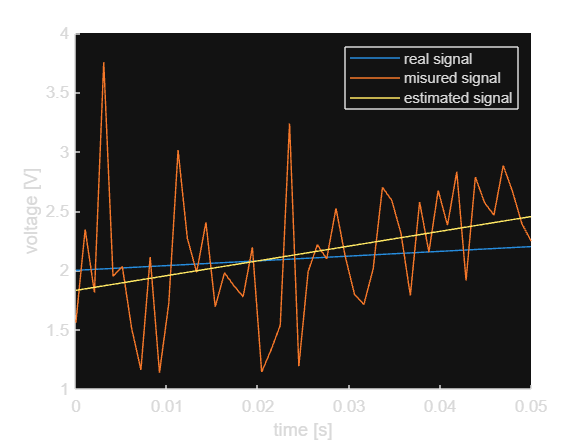

SIZE = 50;
dt = 1e-3;
t = (linspace(0, SIZE, SIZE) * dt)';

theta = [2; 4];

hold on;
x = theta(1) * ones(SIZE, 1) + theta(2) .* t;
y = x + randn(SIZE, 1) * 0.5;
plot(t, x)
plot(t, y)
xlabel('time [s]')
ylabel('voltage [V]')

A = [ones(SIZE, 1), t];
Q = (A'*A)^-1;
C = Q*A';
P = A*C;

theta_hat = C * y;
theta_ = C * x; % should be == theta
x_hat = P * y;
plot(t, x_hat)

legend('real signal', 'misured signal', 'estimated signal')
hold off; clf; clc;

close all force;

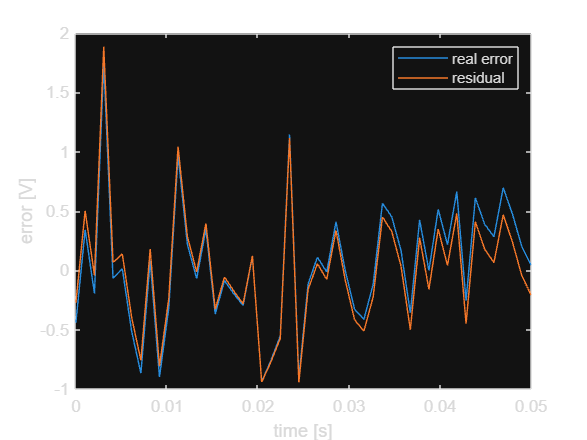

e = y - x;
e_hat = y - x_hat;
plot(t, e)
hold on;
plot(t, e_hat)
xlabel('time [s]')
ylabel('error [V]')
legend('real error', 'residual')


mean_e_hat = mean(e_hat);
var = sum((e_hat - mean_e_hat).^2) / SIZE;
sigma = sqrt(var);

clc;

% Dati
R = 200 % resistenza del circuito (ohm)

R = 200

L = 1e-4 % induttanza del circuito (H)

L = 1.0000e-04

s = tf('s') % variabile s della trasformata di Laplace

s =
 
  s
 
Continuous-time transfer function.
Model Properties


f = 2e5 % frequenza del segnale sinusoidale (Hz)

f = 200000

Vin = 3.5 % ampiezza del gradino vgen(t), nella misura di risposta al gradino

Vin = 3.5000

Vpp1 = 4 % valore picco-picco della sinusoide in ingresso v1(t), nella misura di FRF

Vpp1 = 4

t1 = 9e-7 % istante del primo passaggio per lo zero di v1(t), nella misura di FRF

t1 = 9.0000e-07


Rgen_sol = 50

Rgen_sol = 50

R1_sol = R + Rgen_sol

R1_sol = 250

tau_sol = L/R

tau_sol = 5.0000e-07

tau1_sol = L/R1_sol

tau1_sol = 4.0000e-07

k1_sol = R/R1_sol

k1_sol = 0.8000

Hdot1_sol = k1_sol/(1+s*tau1_sol)

Hdot1_sol =
 
      0.8
  -----------
  4e-07 s + 1
 
Continuous-time transfer function.
Model Properties


Hdot_sol = 1/(1+s*tau_sol)

Hdot_sol =
 
       1
  -----------
  5e-07 s + 1
 
Continuous-time transfer function.
Model Properties



Rgen = 50

Rgen = 50

R1 = R + Rgen

R1 = 250

k1 = R/R1

k1 = 0.8000

tau1 = L/R1

tau1 = 4.0000e-07

tau = L/R

tau = 5.0000e-07

Hdot1 = R / (R1 + s*L) % funzione di trasferimento misurando la risposta al gradino, calcolata in s

Hdot1 =
 
       200
  --------------
  0.0001 s + 250
 
Continuous-time transfer function.
Model Properties


% N
Hdot = R / (R + s*L) % funzione di trasferimento misurando la risposta a una sinusoide single-tone, calcolata in s

Hdot =
 
       200
  --------------
  0.0001 s + 200
 
Continuous-time transfer function.
Model Properties


% N

isequal(Hdot1, Hdot1_sol)

ans = logical
   0


eps

ans = 2.2204e-16

norm(Hdot1 - Hdot1_sol) < eps

ans = logical
   1
